%17 langmuir
P = 0:0.1:1;  %smaller values for practise
b = 0.1:10;
P.*b'

ans =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000
         0    0.1100    0.2200    0.3300    0.4400    0.5500    0.6600    0.7700    0.8800    0.9900    1.1000
         0    0.2100    0.4200    0.6300    0.8400    1.0500    1.2600    1.4700    1.6800    1.8900    2.1000
         0    0.3100    0.6200    0.9300    1.2400    1.5500    1.8600    2.1700    2.4800    2.7900    3.1000
         0    0.4100    0.8200    1.2300    1.6400    2.0500    2.4600    2.8700    3.2800    3.6900    4.1000
         0    0.5100    1.0200    1.5300    2.0400    2.5500    3.0600    3.5700    4.0800    4.5900    5.1000
         0    0.6100    1.2200    1.8300    2.4400    3.0500    3.6600    4.2700    4.8800    5.4900    6.1000
         0    0.7100    1.4200    2.1300    2.8400    3.5500    4.2600    4.9700    5.6800    6.3900    7.1000
         0    0.8100    1.6200    2.4300    3.2400    4.0500    4.8600    5.6700    6.4800    7.2900    8.

1./(1+P.*b')

ans =     1.0000    0.9901    0.9804    0.9709    0.9615    0.9524    0.9434    0.9346    0.9259    0.9174    0.9091
    1.0000    0.9009    0.8197    0.7519    0.6944    0.6452    0.6024    0.5650    0.5319    0.5025    0.4762
    1.0000    0.8264    0.7042    0.6135    0.5435    0.4878    0.4425    0.4049    0.3731    0.3460    0.3226
    1.0000    0.7634    0.6173    0.5181    0.4464    0.3922    0.3497    0.3155    0.2874    0.2639    0.2439
    1.0000    0.7092    0.5495    0.4484    0.3788    0.3279    0.2890    0.2584    0.2336    0.2132    0.1961
    1.0000    0.6623    0.4950    0.3953    0.3289    0.2817    0.2463    0.2188    0.1969    0.1789    0.1639
    1.0000    0.6211    0.4505    0.3534    0.2907    0.2469    0.2146    0.1898    0.1701    0.1541    0.1408
    1.0000    0.5848    0.4132    0.3195    0.2604    0.2198    0.1901    0.1675    0.1497    0.1353    0.1235
    1.0000    0.5525    0.3817    0.2915    0.2358    0.1980    0.1706    0.1499    0.1337    0.1206    0.

P.*b'./(1+P.*b')

ans =          0    0.0099    0.0196    0.0291    0.0385    0.0476    0.0566    0.0654    0.0741    0.0826    0.0909
         0    0.0991    0.1803    0.2481    0.3056    0.3548    0.3976    0.4350    0.4681    0.4975    0.5238
         0    0.1736    0.2958    0.3865    0.4565    0.5122    0.5575    0.5951    0.6269    0.6540    0.6774
         0    0.2366    0.3827    0.4819    0.5536    0.6078    0.6503    0.6845    0.7126    0.7361    0.7561
         0    0.2908    0.4505    0.5516    0.6212    0.6721    0.7110    0.7416    0.7664    0.7868    0.8039
         0    0.3377    0.5050    0.6047    0.6711    0.7183    0.7537    0.7812    0.8031    0.8211    0.8361
         0    0.3789    0.5495    0.6466    0.7093    0.7531    0.7854    0.8102    0.8299    0.8459    0.8592
         0    0.4152    0.5868    0.6805    0.7396    0.7802    0.8099    0.8325    0.8503    0.8647    0.8765
         0    0.4475    0.6183    0.7085    0.7642    0.8020    0.8294    0.8501    0.8663    0.8794    0.

[X,Y] = meshgrid(P,b);

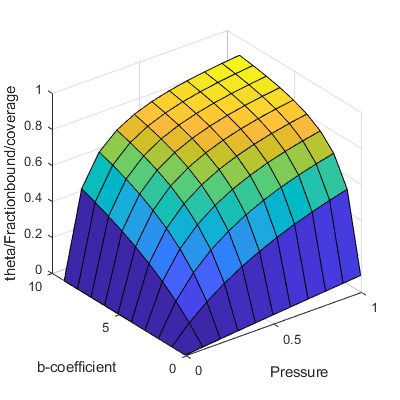

Z = P.*b'./(1+P.*b');
surf(X,Y,Z)
xlabel('Pressure'), ylabel('b-coefficient'), zlabel('theta/Fractionbound/coverage')

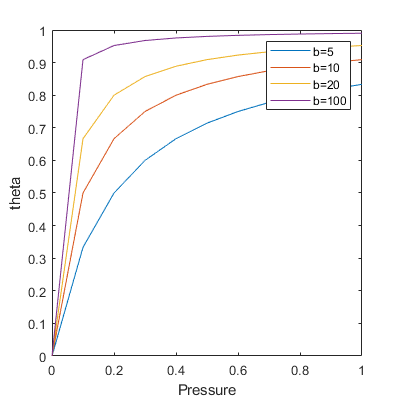

b4 = [5 10 20 100];
theta = P.*b4'./(1+P.*b4');
plot(P, theta)
hold on
xlabel('Pressure'), ylabel('theta')
legend('b=5', 'b=10', 'b=20','b=100');
hold off;